clear
close all
clc

# **TIME SERIES ANALYSIS ON S&P 500 DATASET**

## **Information on the Dataset**

**Title** : S&P 500 stock data

**Source** : Kaggle datasets ([https://www.kaggle.com/camnugent/sandp500](https://www.kaggle.com/camnugent/sandp500))

**Relevant information **:

    One of the most useful real world application of Machine Learning and Data Science in general is the analysis and forecasting of stock market data. The S&P 500 is a stock market index that tracks the stocks of 500 large-cap U.S. companies. This dataset contains historical data of the S&P 500 index (2013 - 2018 [5 years]). Historical data might offer insights on stock markets and might allow us to predict future trends.

**Attribute Information** :

    Each file in the dataset has data in the following format,

- **Date** - in format: yy-mm-dd

- **Open** - Price of the stock at market open (this is NYSE data so all in USD)

- **High** - Highest price reached in the day

- **Low** - Lowest price reached in the data

- **Close **- Price of stock at market close

- **Volume** - Number of shares traded

- **Name** - The stock's ticker name

**The goal of this project is to analyze the APC dataset from S&P 500 dataset by fitting an ARIMA model and try to forecast future stock prices.**

# **AutoRegressive Integrated Moving Average model (ARIMA)**

        ARIMA is one of the most extensively used time series analysis model. It involves autoregression (predict future values based on past vaues), moving average (predict future values based on past errors) and differencing.

## **Loading and cleaning the data**

data = readtable("APC_data.csv");     %Advanced Proteome stock data for ARIMA model
T = table2timetable(data);

%Dropping Name attribute
T = removevars(T, 'Name');

fprintf("Maximum difference between two dates in hours is: %s", max(diff(T.date)))

Maximum difference between two dates in hours is: 96:00:00

As time distribution is not uniform, make difference betweeen successive days to 96 hours (4 days)

T = retime(T, 'regular', 'mean', 'TimeStep', '96:00:00');

## **Exploratory Data Analysis**

#### ***Displaying the table***

head(T)

ans = 8×5 timetable
       date        open      high      low      close       volume  
    __________    ______    ______    ______    ______    __________

    2013-02-08    84.055    84.405     83.57     83.96    1.9499e+06
    2013-02-12    83.672     84.09     82.72    83.415    2.7045e+06
    2013-02-16     82.42     84.13      82.4     84.13    3.2779e+06
    2013-02-20    81.513    82.013    80.038    80.777    3.9325e+06
    2013-02-24    79.847     80.92     77.89    79.063    4.0407e+06
    2013-02-28    79.525    80.275     78.82      79.7    3.3394e+06
    2013-03-04     81.65    82.914    80.694    81.905    3.9072e+06
    2013-03-08    

#### *Plotting all attributes against time*

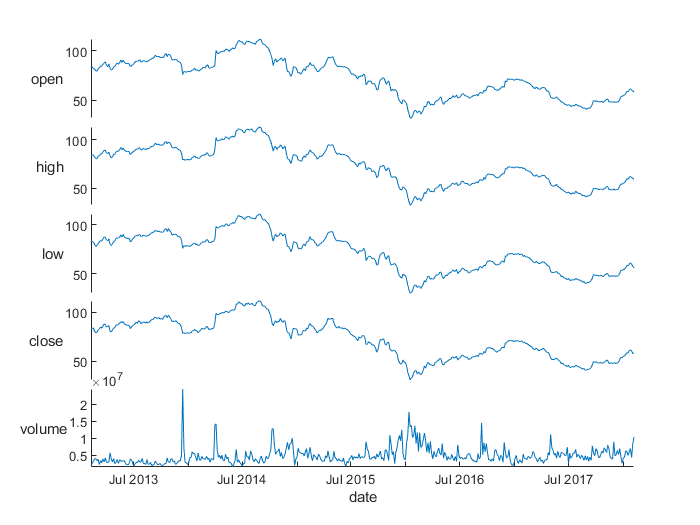

stackedplot(T, {'open', 'high', 'low', 'close', 'volume'});

Let's analyze closing market stock prices a bit closer

#### *Plotting price of stock at market close against time *

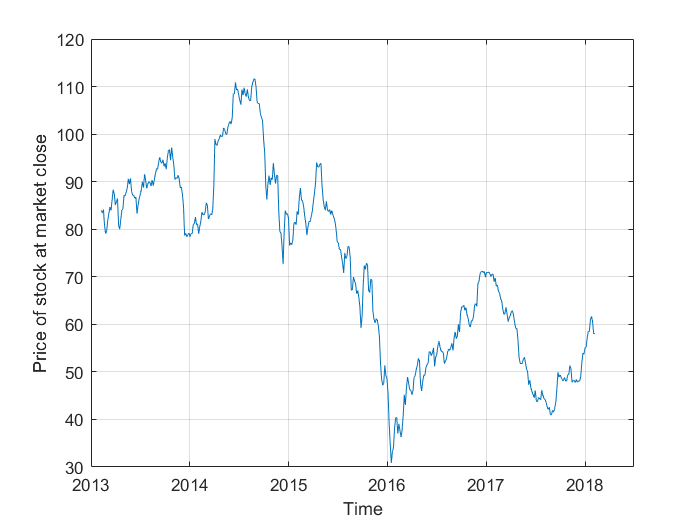

plot(T.date, T.close);
xlabel("Time")
ylabel("Price of stock at market close")
grid on

From the above plot we can see that there is an decreasing trend in the data.

#### *Plotting first order difference of stock at market close versus time*

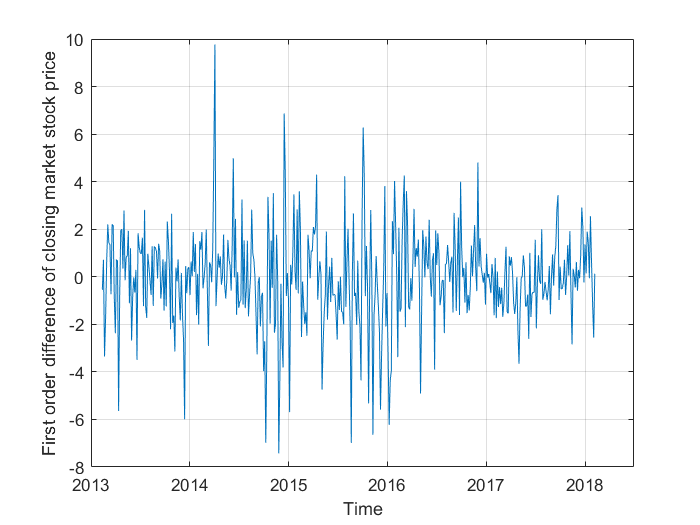

plot(T.date(2:end),diff(T.close));
grid on
ylabel("First order difference of closing market stock price")
xlabel("Time")

        From the above plots we can see that Market close stock prices is not stationary while first order difference is stationary. This can be confirmed by Augmented - Dickey Fuller Test which tests for unit root. If ADF returns 1 then the series is stationary

adftest(T.close)

ans = logical
   0


adftest(diff(T.close))

ans = logical
   1


#### ***Autocorrelation and Partial autocorrelation***

Autocorrelation for first order difference of closing market stock price

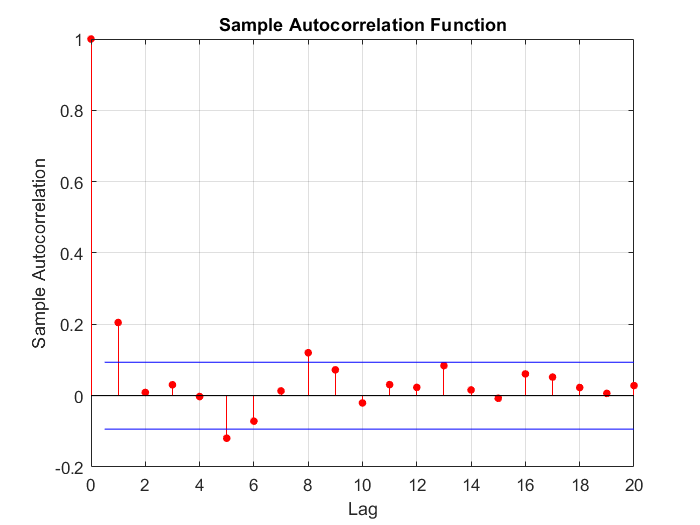

autocorr(diff(T.close))

Partial autocorrelation for first order difference of closing market stock price

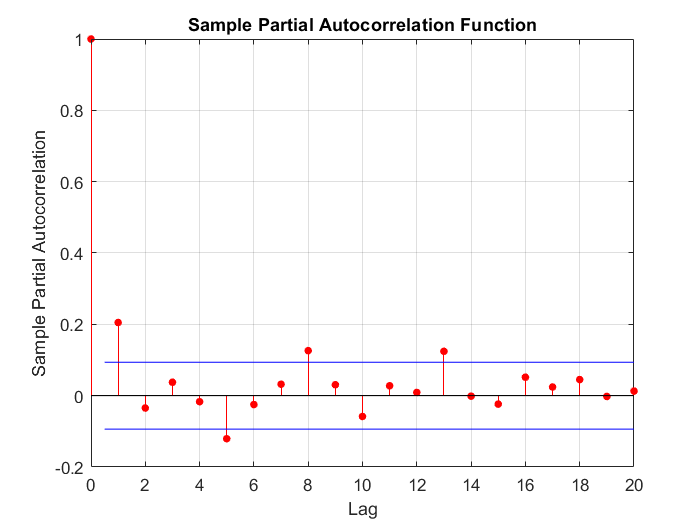

parcorr(diff(T.close))

From the above plots we can see that significant autocorrelation and partial autocorrelation occurs at lag 1.

**From the above analysis we can see that**

- **The market close stock prices is not stationary with respect to time but its first order difference is stationary. Therefore the integration factor of the ARIMA model should be 1 as stationarity is a necsessary condition for ARIMA modelling.**

- **The autocorrelation is somewhat significant for lag 1. Therefore MA parameter should be 1.**

- **The partial autocorrelation is somewhat significant for lag 1. Therefore AR parameter should be 1.**

**Therefore ARIMA(4,1,4) model should be a good fit for this data.**

## **Fitting the model, evaluation and forecasting**** ARIMA(1,1,1)**

#### *Dividing dataset into trains set (70%) and test set (30%)*

b = round(0.7*size(T, 1));
Train = timetable(T.date(1:b), T.close(1:b), 'VariableNames', {'close'});
Test = timetable(T.date(b+1:end), T.close(b+1:end), 'VariableNames', {'close'});

#### *Fitting the ARIMA model*

The model is fit using MATLAB's Econometrics Toolbox

Mdl = arima(1,1,1);
[Estmdl] = estimate(Mdl, Train.close, 'Display', 'off');
summarize(Estmdl)

 
   ARIMA(1,1,1) Model (Gaussian Distribution)
 
    Effective Sample Size: 320
    Number of Estimated Parameters: 4
    LogLikelihood: -703.069
    AIC: 1414.14
    BIC: 1429.21
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    -0.096133       0.15456        -0.62198        0.53396
    AR{1}       -0.019748       0.23729       -0.083222        0.93367
    MA{1}         0.24961       0.24182          1.0322        0.30199
    Variance       4.7413        0.2981          15.905     5.8668e-57

 
 


#### *Residual Analysis*

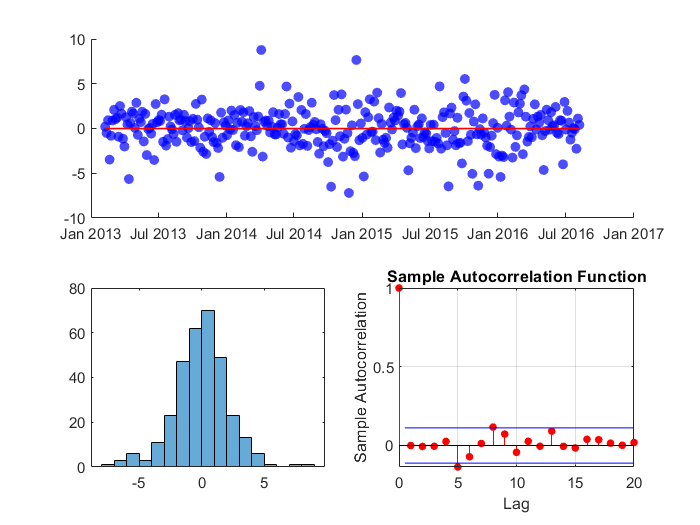

subplot(2,2, [1 2])
res = infer(Estmdl, Train.close);
scatter(Train.Time, res, 'filled', 'b', 'MarkerFaceAlpha', 0.7)
hold on
plot(Train.Time, 0*Train.close, 'red', 'LineWidth', 1)
hold off
subplot(2,2,3)
histogram(res)
subplot(2,2,4)
autocorr(res)

**From the above 3 plots we can see that**

- **Residuals have mean approx. 0.**

- **The residuals are normally distributed**

- **The residuals have no correlation among each other**

**This justifies our model.**

#### *Forecasting*

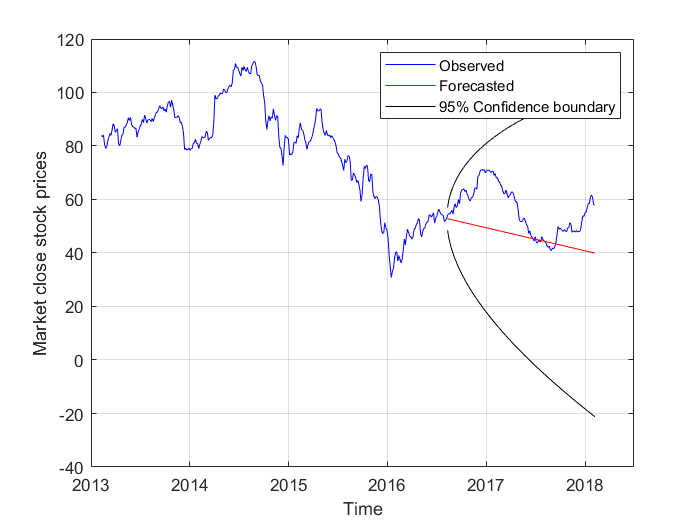

[f, YMSE] = forecast(Estmdl, length(Test.close), Train.close(end-4:end));
upper = f + 1.96*sqrt(YMSE);
lower = f - 1.96*sqrt(YMSE);
figure
plot(T.date, T.close, 'b')
hold on
plot(Test.Time, f, 'r');
plot(Test.Time, upper, 'k')
plot(Test.Time, lower, 'k')
hold off
grid on
ylabel("Market close stock prices")
xlabel("Time")
legend("Observed", "Forecasted", "95% Confidence boundary")

#### *Calculating Error*

MAPE = mean(abs(100*(f - Test.close)./Test.close));
fprintf("The Mean Absolute Percentage Error is : %f", MAPE);

The Mean Absolute Percentage Error is : 16.320087

## **Conclusion**

       In reality stock prices have a lot of factors affecting it. It is hard to predict stock prices solely based on past values as the stock market is very dynamic and volatile in nature. The ARIMA model is a simple model that tries to predict future values just by using the past values and thus the model cannot efficiently predict the prices over the long run. Thus we need more complicated models to forecast something as complicated as stock prices.